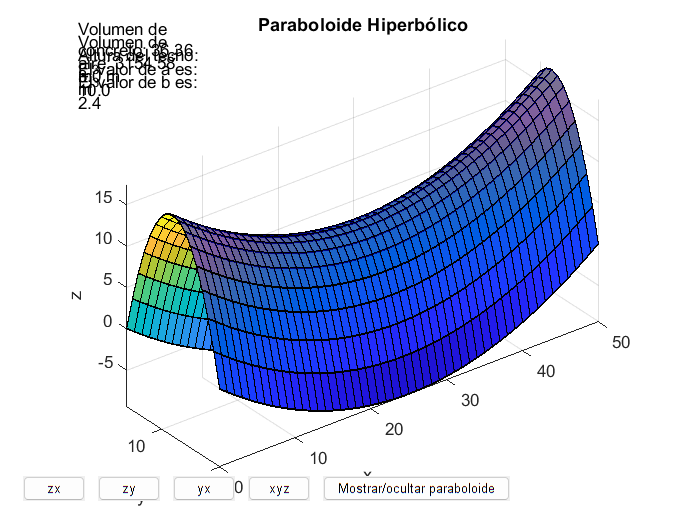

% Solicitar al usuario la altura del techo
prompt = {'Ingrese la altura del techo:'};
dlgtitle = 'Altura del techo';
dims = [1 40];
definput = {'3'};
altura_techo = str2double(inputdlg(prompt, dlgtitle, dims, definput));

% Definición de las dimensiones del paraboloide hiperbólico y parámetros
techo = altura_techo/2; % metros (altura del techo)
ancho = 16; % metros (ancho de la base)
largo = 50; % metros (largo de la base)
alto = 8; % metros (altura de la base)
grosor = 0.12; % metros (grosor del concreto)

a = 10;
b = (8*a).*(sqrt(techo)) / sqrt((625*techo) + (8*a.^2));

% Creación de una malla de puntos (x, y) en el plano xy
[x, y] = meshgrid(-largo/2:1:largo/2, -ancho/2:1:ancho/2);

% Función que define el paraboloide hiperbólico en función de x, y
f = @(x, y) ((x.^2 / (a.^2)) - (y.^2 / (b.^2))) * techo + alto;

% Altura z del paraboloide hiperbólico en función de la posición (x, y)
z = f(x, y);

% Definición de los límites de integración para el primer paraboloide (aire)
z_min = 0; % Altura mínima del primer paraboloide (superficie del suelo)
z_max = @(x, y) f(x, y); % Altura máxima del primer paraboloide (techo)

% Función de densidad variable para el cálculo del volumen (primer paraboloide)
f_integrate = @(x, y, z) (z / alto) .* ones(size(x));

% Cálculo del volumen del aire
V_aire = integral3(f_integrate, -largo/2, largo/2, -ancho/2, ancho/2, z_min, z_max, 'AbsTol', 1e-4, 'RelTol', 1e-4);

% Definición de los límites de integración para el segundo paraboloide (concreto)
z_concreto = 8; % Altura donde comienza el concreto
z_max_concreto = @(x, y) f(x, y) + grosor; % Altura máxima del concreto

% Calcular el área de la superficie donde se encuentra el concreto
area_concreto = sum(sum(z >= z_concreto & z <= z_max_concreto(x, y)));

% Calcular el volumen del concreto multiplicando el área por el grosor
V_concreto = area_concreto * grosor;

% Calcular la carga esperada en base al volumen de concreto
densidad_concreto = 2400; % Densidad del concreto en kg/m^3 (por ejemplo)
carga_esperada = V_concreto * densidad_concreto; % Carga en kg

% Graficar el primer paraboloide
figure;
surf(x+25, y+8, z, 'FaceAlpha', 1); % Opacidad 1 (completamente opaco)
hold on;

% Graficar el segundo paraboloide 12 cm más arriba
z2 = z + grosor; % Aumentar la altura del segundo paraboloide en 12 cm
h_surf = surf(x+25, y+8, z2, 'FaceAlpha', 0.5, 'FaceColor', 'blue'); % Opacidad 0.5 (semi-transparente), color azul

% Configuración de la visualización
title('Paraboloide Hiperbólico');
xlabel('x');
ylabel('y');
zlabel('z');
xlim([-largo/2 largo/2]);
ylim([-ancho/2 ancho/2]);
zlim([0 max(z2(:))]);
view(3);

% Ajuste de la escala de los ejes
axis equal;

% Agregar botones para cambiar las vistas
uicontrol('Style', 'pushbutton', 'String', 'zx', 'Position', [20 20 50 20], 'Callback', @(src, event) view(0, 90));
uicontrol('Style', 'pushbutton', 'String', 'zy', 'Position', [80 20 50 20], 'Callback', @(src, event) view(90, 0));
uicontrol('Style', 'pushbutton', 'String', 'yx', 'Position', [140 20 50 20], 'Callback', @(src, event) view(0, 0));
uicontrol('Style', 'pushbutton', 'String', 'xyz', 'Position', [200 20 50 20], 'Callback', @(src, event) view(3));

% Agregar botón para activar/desactivar el segundo paraboloide
toggle_btn = uicontrol('Style', 'togglebutton', 'String', 'Mostrar/ocultar paraboloide', 'Position', [260 20 150 20], 'Callback', @(src, event) toggleParaboloide(src, h_surf));

% Agregar anotaciones de volumen
annotation('textbox', [0.1, 0.85, 0.2, 0.1], 'String', sprintf('Volumen de aire: %.2f m^3', V_aire), 'EdgeColor', 'none');
annotation('textbox', [0.1, 0.875, 0.2, 0.1], 'String', sprintf('Volumen de concreto: %.2f m^3', V_concreto), 'EdgeColor', 'none');
annotation('textbox', [0.1, 0.825, 0.2, 0.1], 'String', sprintf('Altura del techo: %.1f m', altura_techo), 'EdgeColor', 'none');
annotation('textbox', [0.1, 0.8, 0.2, 0.1], 'String', sprintf('El valor de a es: %.1f', a), 'EdgeColor', 'none');
annotation('textbox', [0.1, 0.775, 0.2, 0.1], 'String', sprintf('El valor de b es: %.1f', b), 'EdgeColor', 'none');


% Calcular las dimensiones de los polines para la cimbra en el techo
% Solicitar al usuario la distancia entre los polines
prompt_polines = {'Ingrese la distancia entre los polines en metros:'};
dlgtitle_polines = 'Distancia entre polines';
dims_polines = [1 50];
definput_polines = {'0.5'}; % Por ejemplo, 50 cm entre polines
distancia_polines = str2double(inputdlg(prompt_polines, dlgtitle_polines, dims_polines, definput_polines));

% Calcular la cantidad de polines necesarios en la dirección de la longitud del techo
cantidad_polines_largo = ceil(largo / distancia_polines);

% Calcular la longitud total de los polines en la dirección de la longitud del techo
longitud_polines_largo = cantidad_polines_largo * distancia_polines;

% Calcular la cantidad de polines necesarios en la dirección del ancho del techo
cantidad_polines_ancho = ceil(ancho / distancia_polines);

% Calcular la longitud total de los polines en la dirección del ancho del techo
longitud_polines_ancho = cantidad_polines_ancho * distancia_polines;

% Calcular la longitud total de los polines necesarios
longitud_total_polines = longitud_polines_largo + longitud_polines_ancho;


% Factor de seguridad para el cálculo del grosor
factor_seguridad = 1.5;

% Calcular el ancho de los polines
ancho_polines = 0.1; % Valor inicial de ancho en metros (por ejemplo)
while true
    % Calcular la carga máxima por unidad de longitud que puede soportar un polín
    carga_maxima_polines = carga_esperada / ancho_polines;
    
    % Dimensiones típicas de polines de madera
    grosor_minimo = 0.05; % Grosor mínimo en metros (por ejemplo)
    
    % Verificar si el grosor calculado es mayor que el grosor mínimo
    if ancho_polines * grosor_minimo * factor_seguridad >= carga_maxima_polines
        break; % Salir del bucle si se cumple la condición
    else
        % Incrementar el ancho de los polines y volver a calcular
        ancho_polines = ancho_polines + 0.01; % Incremento arbitrario (por ejemplo)
    end
end

% Mostrar los resultados
disp(['El alto es: ', num2str(altura_techo), ' metros']);

El alto es: 3 metros


disp(['El volumen del aire es: ', num2str(V_aire), ' m^3']);

El volumen del aire es: 3154.5833 m^3


disp(['El volumen del concreto es: ', num2str(V_concreto), ' m^3']);

El volumen del concreto es: 36.36 m^3



% Mostrar resultados de los polines
disp(['Se necesitarán ', num2str(cantidad_polines_largo), ' polines a lo largo del techo.']);

Se necesitarán 100 polines a lo largo del techo.


disp(['Se necesitarán ', num2str(cantidad_polines_ancho), ' polines a lo ancho del techo.']);

Se necesitarán 32 polines a lo ancho del techo.


disp(['La longitud total de los polines necesarios es de ', num2str(longitud_total_polines), ' metros.']);

La longitud total de los polines necesarios es de 66 metros.



% Mostrar los resultados
disp(['Ancho total de los polines necesario: ', num2str(ancho_polines), ' metros']);

Ancho total de los polines necesario: 1078.67 metros


disp(['Grosor total de los polines necesario: ', num2str(ancho_polines * grosor_minimo * factor_seguridad), ' metros']);

Grosor total de los polines necesario: 80.9002 metros


function toggleParaboloide(src, h_surf)
    if get(src, 'Value')
        set(h_surf, 'Visible', 'on');
    else
        set(h_surf, 'Visible', 'off');
    end
end